# standardize card image

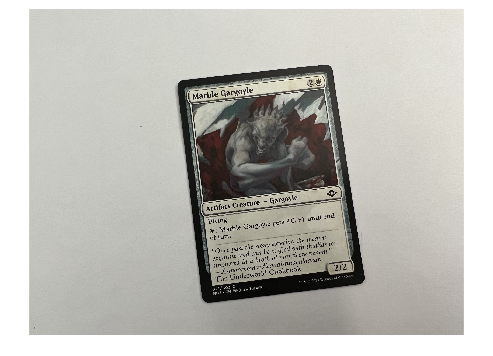

realImg = imread("im4.JPG");
ogImg = realImg;
figure;
imshow(realImg);

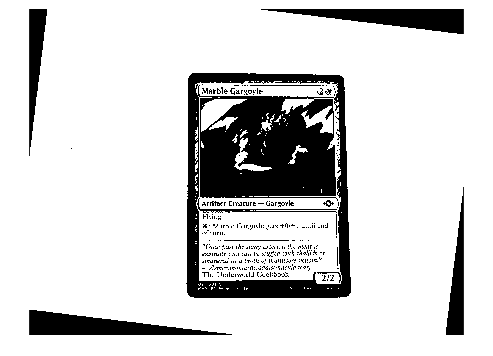


realImg = rgb2gray(realImg);
realImg = medfilt2(realImg);
realImg = imbinarize(realImg,graythresh(realImg));

% % Apply edge detection to obtain binary edges
% edges = edge(realImg, 'Canny'); % You can choose other edge detection methods as well
% 
% % Multiply the binary edge map with the original image to extract only the contour pixels
% contourImage = realImg;
% contourImage(repmat(~edges, [1, 1, size(realImg, 3)])) = 1; % Set non-edge pixels to zero
% 
% % Display the original image and the contour image side by side
% subplot(1,2,1);
% imshow(realImg);
% title('Original Image');
% subplot(1,2,2);
% imshow(contourImage);
% title('Contours Only');


% % Obtain the boundary coordinates using bwboundaries function
% boundaries = bwboundaries(edges);
% 
% % Display the original image
% imshow(realImg);
% hold on;
% 
% % Plot the contour points on top of the original image
% for k = 1:length(boundaries)
%     boundary = boundaries{k};
%     
%     plot(boundary(:, 2), boundary(:, 1), 'r', 'LineWidth', 2); 
% end


[h,l,t] = hough(edge(realImg,"sobel"));
peaks = houghpeaks(h,1);
lines = houghlines(edge(realImg,"sobel"),l,t,peaks);

angle = atan2(lines(1).point2(2)-lines(1).point1(2),lines(1).point2(1)-lines(1).point1(1));
corrected = imrotate(realImg,rad2deg(angle)-90,'bilinear','crop');

figure;
imshow(corrected);

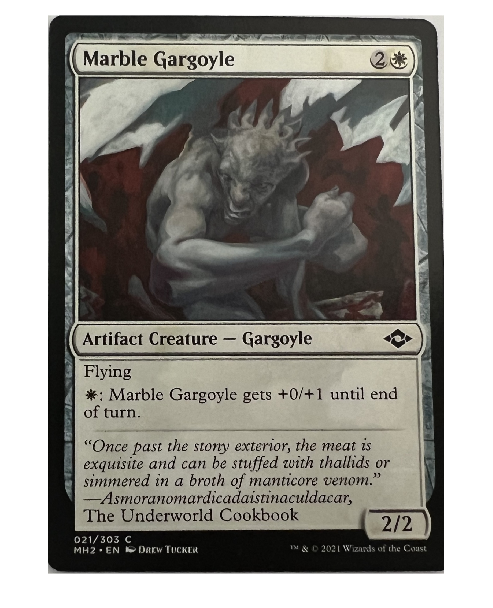


[r,c] = size(corrected);


northmost = r;
southmost = 1;
westmost = c;
eastmost = 1;

for i=r/2-1:r/2+1
    for j=1:c
        if corrected(i,j) == 0
            if j < westmost
                westmost = j;
            end
            if j > eastmost
                eastmost = j;
            end
        end
    end
end

for i=r/2-1:r/2+1
    for j=c:1
        if corrected(i,j) == 0
            if j < eastmost
                eastmost = j;
            end
        end
    end
end

for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i < northmost
                northmost = i;
             
            end
        end
    end
end


for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i > southmost
                southmost = i;
               
            end
        end
    end
end

cropRect = [westmost northmost (eastmost - westmost) (southmost - northmost)];
ogImg = imrotate(ogImg,rad2deg(angle)-90,'bilinear','crop');
croppedImg = imcrop(ogImg,cropRect);
figure;
imshow(croppedImg);

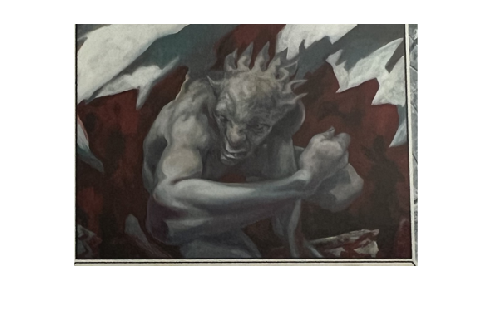


% get
test = imread("https://cards.scryfall.io/art_crop/front/1/4/1465ca9e-a997-4b8c-9677-6c7961f67eba.jpg?1562628773");

% queries
% color
% text
card = croppedImg;
%[card1, ArtCropRect] = imcrop(card);
%normalSize = [680 488];
%card = imresize(card, normalSize);
%imshow(card);
ArtCropRect = [109.510000000000, 243.510000000000, 1286.98000000000, 922.980000000000];
card = imcrop(card, ArtCropRect);

artCropSize = [291 413];
card = imresize(card, artCropSize);
dinner1 = card;
imshow(card)

card1 = rgb2gray(card);

%points =  detectSIFTFeatures(card1);
%imshow(card1);
%hold on;
%plot(points.selectStrongest(1421))

% Extract SIFT keypoints and descriptors
points = detectSIFTFeatures(card1);
[descriptors, ~] = extractFeatures(card1, points);

% Normalize descriptors
descriptors_norm = bsxfun(@rdivide, descriptors, sqrt(sum(descriptors.^2,2)));

% Hash descriptors
hash_code2 = '';
threshold = mean(descriptors_norm(:)); % Randomly chosen threshold
for i = 1:size(descriptors_norm,1)
    descriptor = descriptors_norm(i,:);
    binary_val = '';
    for j = 1:length(descriptor)
        if descriptor(j) > threshold
            binary_val = strcat(binary_val,'1');
        else
            binary_val = strcat(binary_val,'0');
        end
    end
    hash_code2 = strcat(hash_code2,binary_val);
end

% Return hash code
hash_code2

hash_code2 = '00000000110000000001100000011000000000001000100000011100000110110000000010000000100011100000011100000000100000001000110000000000011000001100000000011000000000000110000011100000100110000000000000100011100010110001100000000000100000010000100100001000000000000000000000000000000000100000001000000000100000110000001100000010000000001000000110000011000000100000000011000000110000000000000000000000100000011000000100000000000000001100000111100000001000000000000011100000011000000010000000000000000000000000000000100000110001101100000001110000001100001110000011000001000111000011110011000001110000011000110000001100110000011000000110011001000010000000001010000011100000010000000101100000111000011000000100000000111000001100000110000001000000000000000110000001100000010000000011000000110000001000000000000000100000101000000110000000000000001000010011000000110000000000000001000000100000011000000010000000000000001100000011000000000000000000000011000000110000001000000000100000110000011100000110

## Get answer DCT

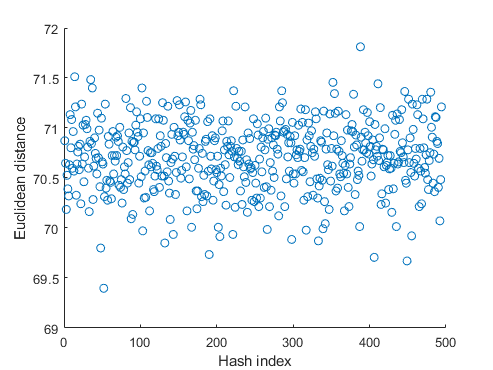

% Choose two hashes to compare (e.g., hashes 1 and 2)
%hash1 = hash_array(1,:);
%hash2 = hash_array(2,:);

% Compute the Hamming distance
%hamming_dist = sum(xor(hash1, hash2));

load('hash.mat');
load('hash_map.mat')
[r,c] = size(hash_array);

% Choose two hashes to compare (e.g., hashes 1 and 2)
hash1 = hash_array(1,:);
theHash = zeros(2500);

lowestDist = 100000;

%Get card to compare
tempCard = card;
gray_card = rgb2gray(tempCard);
% Apply DCT
dct_img = dct2(gray_card);
% Extract the high-frequency components
num_coeffs = num_coeff;
high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);
% Generate the hash
threshold = mean(high_coeffs(:));
hash = high_coeffs > threshold;
hash1 = reshape(hash, 1, []);

distance_values=[];
% iterate through the hash_array
for i=1:r
    hash2 = hash_array(i,:);
    % Compute the Hamming distance
    hamming_dist = sum(xor(hash1, hash2));
    % Compute the Euclidean distance
    euclidean_dist = pdist([hash1; hash2], 'euclidean');
    distance_values= [distance_values euclidean_dist];
    if euclidean_dist < lowestDist
        lowestDist = euclidean_dist;
        theHash = hash2;
    end
end


figure;
scatter(1:r, distance_values);
xlabel('Hash index');
ylabel('Euclidean distance');

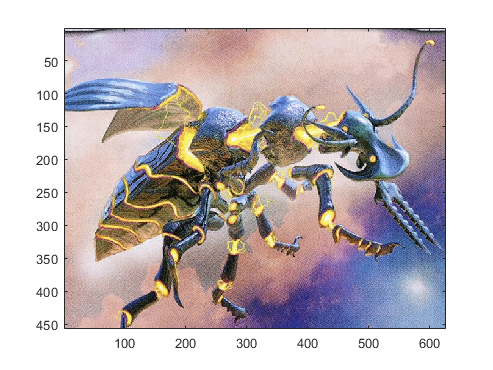


hashKey = sprintf('%d', hash_array(193,:));
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

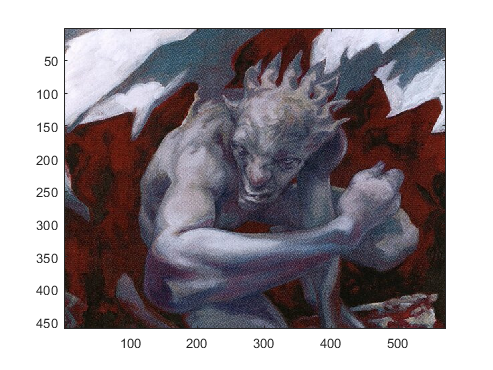


hashKey = sprintf('%d', theHash);
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

## DCT hashing entire json

jsonStr = fileread('dmuset_artcrop.json');
jsonData = jsondecode(jsonStr);

% creating temp files for storage
%tempCard = imread(cell2mat(jsonData(1)));
%gray_card = rgb2gray(tempCard);
num_coeff = 100;
hash_array = zeros(length(jsonData), num_coeff*num_coeff);

hash_map = containers.Map;

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);
    % INCLUDE LINE BELOW FOR 
    %gray_card = imcrop(gray_card, cardCrop);
    gray_card = imresize(gray_card, artCropSize);
    %gray_card = imcrop(gray_card, [130.5 268.5 1505. 1305]);
    % Apply DCT
    dct_img = dct2(gray_card);

    % Extract the high-frequency components
    num_coeffs = num_coeff;
    high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);

    % Generate the hash
    threshold = mean(high_coeffs(:));
    hash = high_coeffs > threshold;
    hash = reshape(hash, 1, []);

    % Store the hash in the hash array
    hash_array(i,:) = hash;
    cell2mat(jsonData(i));
    hash_str = sprintf('%d', hash);
    hash_map(hash_str) = cell2mat(jsonData(i));



end

save('hash_map.mat', 'hash_map');
save('hash.mat', 'hash_array');


## SIFT hashing entire json

jsonStr = fileread('mh2set_artcrop.json');
jsonData = jsondecode(jsonStr);

% creating temp files for storage
%tempCard = imread(cell2mat(jsonData(1)));
%gray_card = rgb2gray(tempCard);
num_coeff = 100;
hash_arraySIFT2 = cell(1, length(jsonData));

hash_mapSIFT2 = containers.Map;

maxLength = 0;

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);

    points = detectSURFFeatures(gray_card);
    [features, valid_points] = extractFeatures(gray_card,points);

    threshold = mean(features);

    features_quantize = features > threshold;

    hash_val = features_quantize(:);
    hash_val = double(hash_val);

    if length(hash_val) > maxLength
        maxLength = length(hash_val);
    end

    % Store the hash in the hash array
    hash_arraySIFT2{i} = hash_val;
end

maxLength = 118400;
for i=1:size(hash_arraySIFT2,2)
    if length(hash_arraySIFT2{i}) < maxLength
        hash_arraySIFT2{i} = permute(hash_arraySIFT2{i}, [2, 1]);
        padding = zeros(1, maxLength-length(hash_arraySIFT2{i}));
        hash_arraySIFT2{i} = [hash_arraySIFT2{i} padding];
        hash_str = sprintf('%d', hash_arraySIFT2{i});
        hash_mapSIFT2(hash_str) = cell2mat(jsonData(i));
    end
end

save('hash_mapSIFT2.mat', 'hash_mapSIFT2');
save('hashSIFT2.mat', 'hash_arraySIFT2');

load('hash_mapSIFT2.mat')
load('hashSIFT2.mat')
[r,c] = size(hash_arraySIFT2);

tempCard = card;
gray_card = rgb2gray(tempCard);

points = detectSURFFeatures(gray_card);
[features, valid_points] = extractFeatures(gray_card,points);

threshold = mean(features);

features_quantize = features > threshold;

hash_val = features_quantize(:);
hash_val = double(hash_val);
maxLength = 118400;
hash_val = permute(hash_val, [2, 1]);
if length(hash_val) < maxLength
    padding = zeros(1, maxLength-length(hash_val));
    hash_val = [hash_val padding];
end

finalHash2 = hash_val;
lowestDist = 1000000;
distance_values=[];
% iterate through the hash_array
for i=1:c
    hash2 = hash_arraySIFT2{i};
    %hash2 = permute(hash2, [2, 1]);
    hash2 = reshape(hash2, [1,maxLength]);
    % Compute the Hamming distance
    %hash_val = permute(hash_val, [2, 1]);
    hamming_dist = pdist([hash_val; hash2], 'euclidean');
    % Compute the Euclidean distance
    distance_values = [distance_values hamming_dist];
    if  hamming_dist < lowestDist
        lowestDist =  hamming_dist;
        finalHash2 = hash2;
    end
end
finalHash2

finalHash2 =      1     1     1     0     1     0     0     1     1     1     0     0     0     0     1     1     0     0     1     1     0     1     0     0     0     0     0     1     1     0     1     1     0     0     1     1     1     1     1     1     0     0     0     1     1     1     1     0     0     0


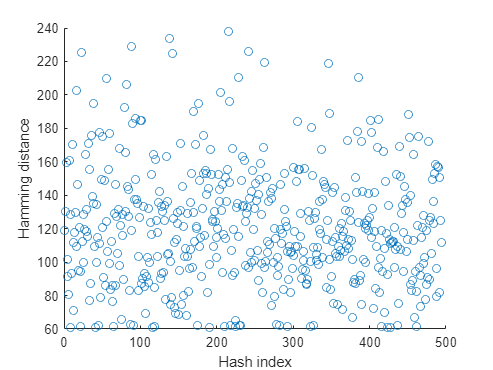


figure;
scatter(1:c, distance_values);
xlabel('Hash index');
ylabel('Hamming distance');

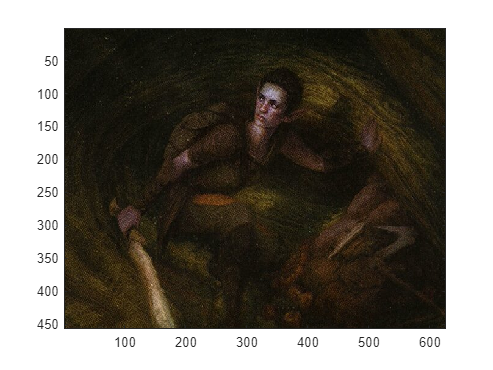



%hashKey = sprintf('%d', hash_arraySIFT2{215});
%cardURL = hash_mapSIFT2(hashKey);
%cardFinalImage = imread(cardURL);
%imagesc(cardFinalImage);

testHash = hash_arraySIFT2{215};
testHash = reshape(testHash, [1,maxLength]);
hashKey = sprintf('%d', testHash);
hashKey = sprintf('%d', finalHash2);
cardURL = hash_mapSIFT2(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

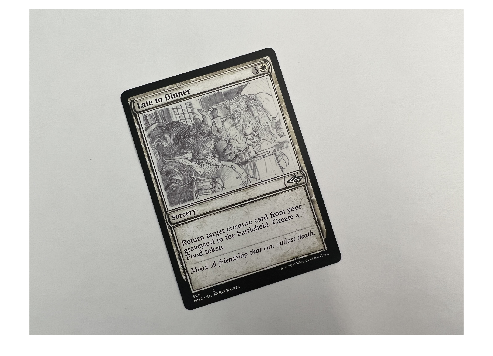

dinner1 = imread("dinner.jpg");
dinner2 = imread("https://cards.scryfall.io/art_crop/front/e/9/e94e53f0-cfca-4b40-9867-94ea771463cd.jpg?1626100889");
imshow(dinner1)

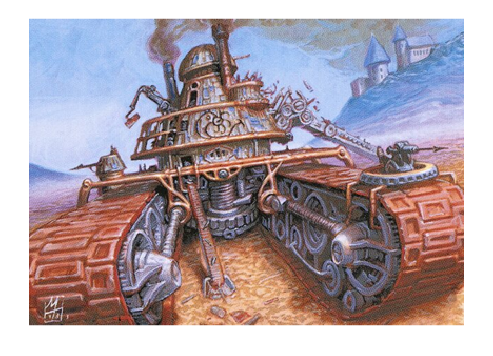

dinner2 = imresize(dinner2, artCropSize);
imshow(dinner2)
dinner1 = rgb2gray(dinner1);
dinner2 = rgb2gray(dinner2);
points1 = detectSURFFeatures(dinner1);
points2 = detectSURFFeatures(dinner2);
[f1,vpts1] = extractFeatures(dinner1,points1);
[f2,vpts2] = extractFeatures(dinner2,points2);

indexPairs = matchFeatures(f1,f2) ;
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

figure; showMatchedFeatures(dinner1,dinner2,matchedPoints1,matchedPoints2);

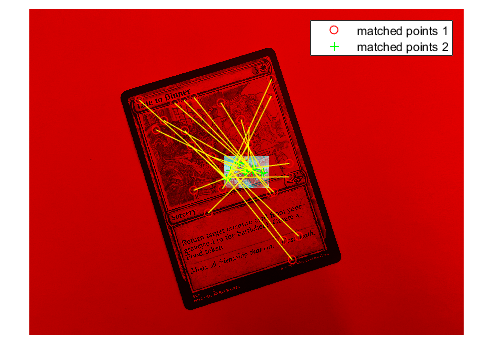

legend('matched points 1','matched points 2');